clear;clc;close all;

R = 10;
L = 0.01;
C = 1e-6;

% 2.定义复频域算子 s
s = tf('s');

% 3.建立开环传递函数 G(s)
G = 1 / (L*C*s^2 + R*C*s + 1);

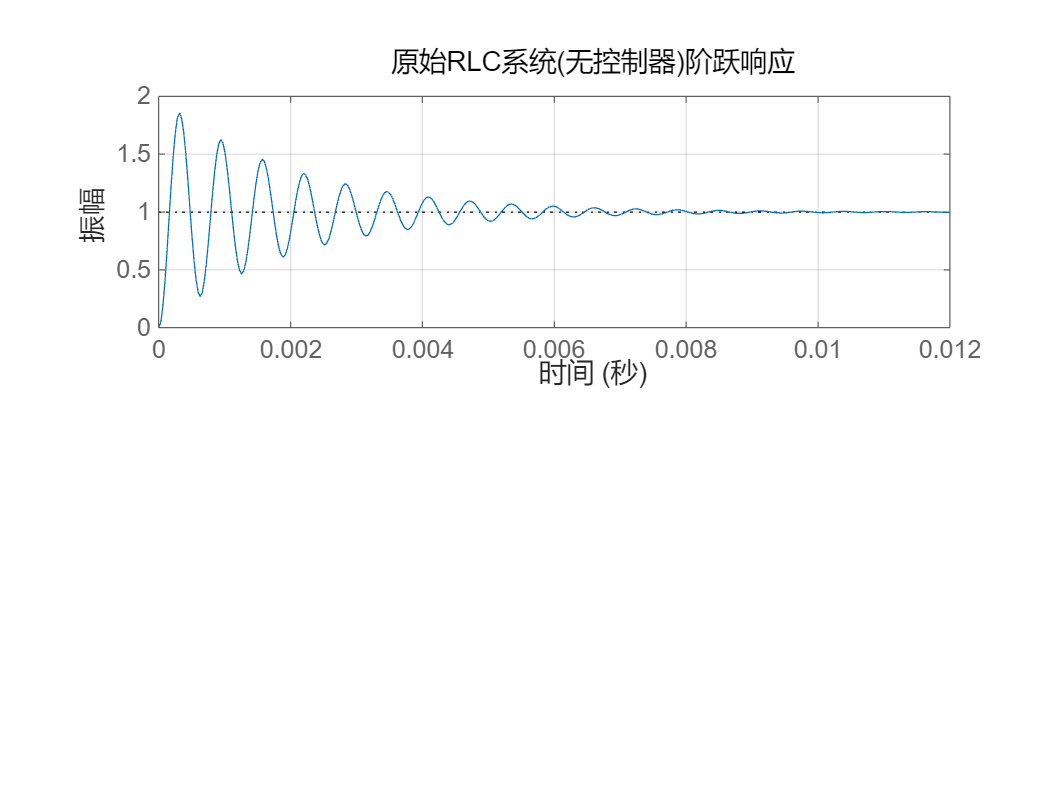

figure;
subplot(2,1,1);
step(G);
grid on;
title('原始RLC系统(无控制器)阶跃响应');

% 5.增加PID控制器
C_pid = pid(100, 10, 0.1); % Kp=100, Ki=10, Kd=0.1

% 6.建立闭环系统 T(s)
T = feedback(C_pid * G, 1)

T =
 
        0.1 s^2 + 100 s + 10
  --------------------------------
  1e-08 s^3 + 0.1 s^2 + 101 s + 10
 
连续时间传递函数。
模型属性


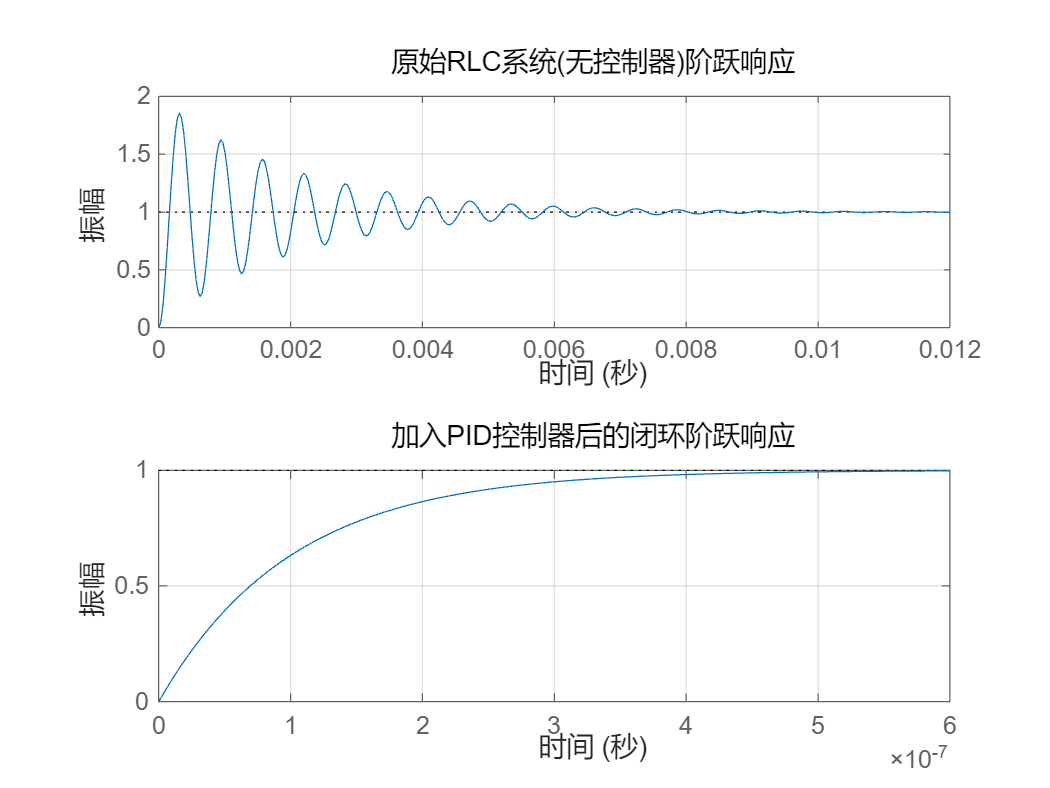

% 7.对比控制前后的阶跃响应
subplot(2,1,2);
step(T);
grid on;
title('加入PID控制器后的闭环阶跃响应');